# Lap Time Simulation

## 使い方

- vehicle_parameter_nit00.mlxでパラメータ設定

- GGV_map_creation_4.mlxで車両のGGV Mapを作成

- 走るコースを決め，Lap Time Simulation !

一度，GGV Mapを作成した車両に関しては，保存されている

GGV_Map_nit00_00.matを読み込んでシミュレーションするので，

1, 2を行う必要はありません

### 注意事項

コースのエクセルはすでにあるものと，まったく同じように作成してください

### 計算結果は一番下に表示されます

### 初期化

cd(fileparts(matlab.desktop.editor.getActiveFilename))
clc
clear variables
close all
%おまじないなので触らない

### シミュレーション条件設定

%% コースデータ読み込み

% コメントアウトを変更してコースを変更
% trackfile = 'nit23_ecopa_50_kawai.xlsx'; % ecopa 50kW
% trackfile = 'nit23_ecopa_endurance_kawai.xlsx'; % ecopa 30kW
% trackfile = 'nit23_ASE_endurance_kawai.xlsx'; % ASE Endurance 30kW
trackfile = 'nit23_ASE_autoX_kawai.xlsx'; %ASE Auto X 50kW

%% 走行車両GGV Map
vehicle_name = 'nit23_50'; % 車両名 図を保存するときにタイトルになる
vehicle_sim = 'GGV_map_nit23_50.mat'; % 要変更 車両GGV Map

%% スタート地点での速度(0以外)
start_v = 47; % [km/h]

%% ドライバー練度
driver_acc = 0.8; %ドライバーの加速のうまさ
driver_dec = 0.8; %ドライバーの減速のうまさ
driver_cor = 0.9; %ドライバーのコーナリングのうまさ

%% グラフに表示するデータの選択
mode = 0; % 速度マップ
% mode = 1; % 横Ｇマップ
% mode = 2; % 前後Ｇマップ

### コース設定

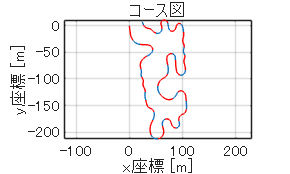

% -----------------------------------------------------------
% ここから下はラップタイムシミュレーションを行うセクションです
% 修正を加える場合は中身を理解した上で行ってください
% -----------------------------------------------------------

%コース読み込み
trackdata = readmatrix(trackfile, 'Range', 'C18'); % ExcelのC18より右下をすべて抜き出す

lat = trackdata(:,5); % trackdataの経度
lon = trackdata(:,4); % trackdataの緯度
origin = [lon(1),lat(1),0]; % 原点をスタート地点に設定
[x,y] = latlon2local(lon, lat, 0, origin); % 緯度経度→デカルト座標
plot(x,y)
grid on
title("コース図");
xlabel("x座標 [m]")
ylabel("y座標 [m]")
axis equal; % xyを1:1にする

% 累積距離を計算
dist = [0; cumsum(sqrt(diff(x).^2 + diff(y).^2))];

% 0.5m間隔の距離ベクトルを作成
s_interp = (0:0.5:dist(end))';

% 三次スプラインで座標をリサンプリング
x_smooth = interp1(dist, x, s_interp, 'spline');
y_smooth = interp1(dist, y, s_interp, 'spline');
v_smooth = interp1(dist, trackdata(:,3), s_interp, 'spline');

% 確認用プロット
hold on;
plot(x_smooth, y_smooth, 'r--'); % 滑らかになったライン
hold off


% グラディエントを計算
dx  = gradient(x_smooth, 0.5);
ddx = gradient(dx, 0.5);
dy  = gradient(y_smooth, 0.5);
ddy = gradient(dy, 0.5);

% 曲率の公式
kappa = (dx.*ddy - dy.*ddx) ./ (dx.^2 + dy.^2).^(1.5);

% ノイズが残る場合はさらに移動平均
kappa = smoothdata(kappa, 'gaussian', 5);

% 各点間の距離を再計算
ds = [0; sqrt(diff(x_smooth).^2 + diff(y_smooth).^2)];

% 累積距離ベクトル (これが速度プロファイルの横軸になります)
s_accumulated = cumsum(ds);

% 全走距離（コース長）
total_length = s_accumulated(end);
fprintf('コース長: %.2f m\n', total_length);

コース長: 846.93 m


### ラップタイムシミュレーション

load(vehicle_sim); % GGV Map読み込み

% 単位変換
G2MS = 9.80665;
KMH2MS = 1/3.6;

% GGVデータの単位変換と準備
ax_map = GGV(:,:,1) * G2MS; 
ay_map = GGV(:,:,2) * G2MS;
v_map  = GGV(:,:,3) * KMH2MS; 

% 加速側の補間関数
ax_map_acc = ax_map(:,1:44); % GGV Map中の加速のみ
ay_map_acc = ay_map(:,1:44);
v_map_acc = v_map(:,1:44);
F_acc = scatteredInterpolant(ay_map_acc(:)*driver_acc, v_map_acc(:), ax_map_acc(:));

% 減速側の補間関数
ax_map_dec = ax_map(:,45:88); % GGV Map中の減速のみ
ay_map_dec = ay_map(:,45:88);
v_map_dec = v_map(:,45:88);
F_dec = scatteredInterpolant(ay_map_dec(:)*driver_dec, v_map_dec(:), ax_map_dec(:)); % ここ警告出るけど特に問題ない


v_vec = v_map(:,1); % 速度ベクトル [m/s]
ay_limit_vec = max(abs(ay_map), [], 2)*driver_cor; % 各速度での最大横G [m/s^2]

% 旋回限界速度 (V_limit) の計算
v_limit = zeros(size(kappa));
v_test = linspace(0.1, max(v_vec), 200); % 探索用の速度軸

for i = 1:length(kappa)
    if abs(kappa(i)) < 1e-4 % 曲率がすごく小さいとき
        v_limit(i) = max(v_vec); % 直線区間
    else
        % 必要横G (v^2 * kappa) と車両限界を照合
        ay_req = (v_test.^2) * abs(kappa(i)); % 必要G
        ay_max_at_v = interp1(v_vec, ay_limit_vec, v_test, 'linear', 'extrap'); % 車両限界を線形補間で求める

        idx = find(ay_req <= ay_max_at_v, 1, 'last'); % 最大を探索
        if isempty(idx)
            % もし一つも見つからない（極低速でも曲がれない）場合は、
            % 探索範囲の最小値を入れることでエラーを防ぐ
            v_limit(i) = v_test(1);
        else
            v_limit(i) = v_test(idx);
        end
    end
end

% Forward Pass (加速限界の計算)
v_fwd = zeros(size(s_accumulated));
v_fwd(1) = start_v * KMH2MS; % スタート速度

for i = 1:length(s_accumulated)-1
    v_curr = v_fwd(i); % 今の速度
    ay_req = (v_curr^2 * abs(kappa(i))); % 現在の必要横G

    % GGVから出せる最大加速を引き出す (interp2)
    % 境界条件エラー回避のためay_reqを車両限界の99%以内に制限
    ay_max_curr = interp1(v_vec, ay_limit_vec, v_curr); % 車両限界を線形補間
    ay_query = min(ay_req, ay_max_curr * 0.99);

    ax_acc = F_acc(ay_query, v_curr); %減速加速度を補間
    ax_acc = max(0, ax_acc); % 加速のみ抽出

    % 速度更新
    v_next = sqrt(v_fwd(i)^2 + 2 * ax_acc * 0.5);
    v_fwd(i+1) = min(v_next, v_limit(i+1));
end

% Backward Pass (減速限界の計算)
v_bwd = zeros(size(s_accumulated));
v_bwd(end) = v_fwd(end);

for i = length(s_accumulated):-1:2
    v_curr = v_bwd(i);
    ay_req = (v_curr^2 * abs(kappa(i)));

    ay_max_curr = interp1(v_vec, ay_limit_vec, v_curr); % 車両限界を線形補間
    ay_query = min(ay_req, ay_max_curr * 0.99);

    ax_dec = F_dec(ay_query, v_curr); %加速加速度を補間
    ax_dec = min(0, ax_dec); % 減速(負)のみ抽出

    % 速度更新 (逆向き)
    v_prev = sqrt(v_bwd(i)^2 + 2 * abs(ax_dec) * 0.5);
    v_bwd(i-1) = min(v_prev, v_limit(i-1));
end

% 最終結果の統合
v_final = min(v_fwd, v_bwd); % 各座標での通過速度
lap_time_sim = sum(ds ./ v_final); %シミュレーションタイム
lap_time_real = sum(ds ./ (v_smooth*KMH2MS)); %実測タイム
fprintf('Simulation Time: %.3f s\nRecorded Time: %.3f s', ...
    lap_time_sim,lap_time_real);

Simulation Time: 61.876 s
Recorded Time: 63.681 s


% simの横G，前後G計算
ay_sim = (v_final.^2) .* (kappa/G2MS);
ax_sim = [diff(v_final.^2) / (2 * 0.5)/G2MS; 0];

% 結果ログの作成
sim_log_data = [ds ./ v_final, cumsum(ds), v_final/KMH2MS, ay_sim, ax_sim];
%               タイム        , 走行距離   , 速度          , 横G   , 前後G

### 可視化

% 図のタイトル作成
current_date = datestr(now, 'yy-mm-dd_HH-MM'); % 非推奨と出るが問題はない
figure_title = [vehicle_name, '_', current_date]; % 車両名 + 日付
figure('Name', figure_title, 'NumberTitle', 'off'); % 図のタイトル

% 速度ログ(simと走行ログ比較)
subplot(2,2,[1 2]);
plot(s_accumulated, v_final * 3.6, 'k', 'LineWidth', 2); 
hold on;
plot(s_accumulated, v_smooth, 'r', 'LineWidth', 1);
grid on;
xlabel('走行距離 [m]');
ylabel('速度 [km/h]'); 
legend('simulation','log data');
title('速度 - 走行距離');

% コース上での分布
subplot(2,2,3);
mode

mode = 0

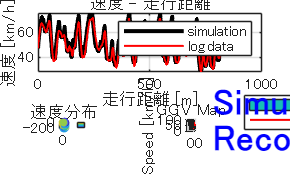

if mode == 0
    scatter(x_smooth, y_smooth, 15, v_final/KMH2MS, 'filled');
    title('速度分布')
elseif mode == 1
    scatter(x_smooth, y_smooth, 15, ay_sim, 'filled');
    title('横G分布')
elseif mode == 2
    scatter(x_smooth, y_smooth, 15, ax_sim, 'filled');
    title('前後G分布')
else
    title('mode error !','Color','r')
end
axis equal
grid on
colorbar
xlabel('x座標 [m]')
ylabel('y座標 [m]')

% GGV Map (sim走行軌跡)
subplot(2,2,4);
surf(GGV(:,:,2),GGV(:,:,1),GGV(:,:,3),'FaceAlpha',0.5)
title('GGV Map')
xlabel('Lat acc [G]')
ylabel('Long acc [G]')
zlabel('Speed [km/h]')
view(105,5)
set(gca,'DataAspectRatio',[1 1 20])
hold on
plot3(ay_sim,ax_sim,v_final/KMH2MS,'r',"LineWidth",1);
legend("GGV Map", "Simulation")

% ラップタイム表示
annotation('textbox', [0.7, 0.45, 0.3, 0.1], ...
    'String', sprintf('Simulation Time : %.3f s \nRecorded Time  : %.3f s', ...
    lap_time_sim, lap_time_real), ...
    'FontSize', 18, ...
    'FontWeight', 'bold', ...
    'Color', 'blue', ...
    'EdgeColor', 'none', ...
    'FitBoxToText', 'on');